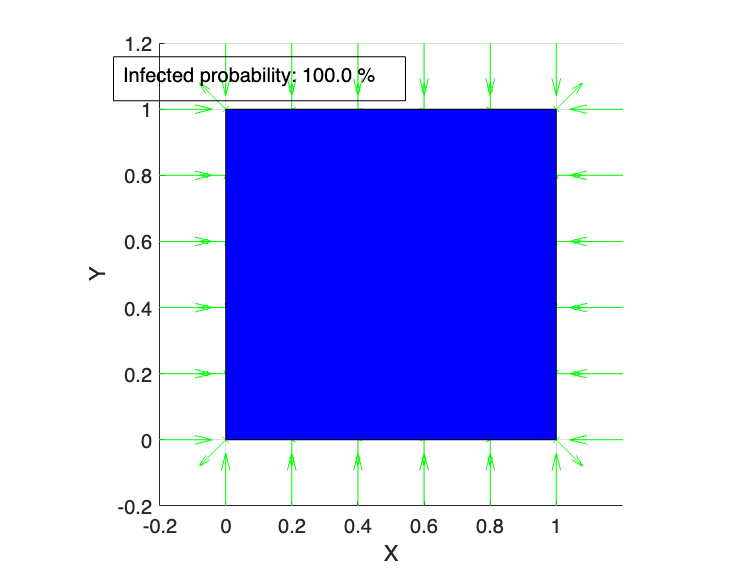

vertices = [
    1, 1, 0;
    1, 0, 0;
    0, 0, 0;
    0, 1, 0;
    1, 1, 0.2;
    1, 0, 0.2;
    0, 0, 0.2;
    0, 1, 0.2;
    
    1, 1, 1;
    1, 0, 1;
    0, 0, 1;
    0, 1, 1;
    1, 1, 1.2;
    1, 0, 1.2;
    0, 0, 1.2;
    0, 1, 1.2;
];

faces = [
    1, 2, 3, 4;
    5, 6, 7, 8;
    1, 5, 6, 2;
    2, 6, 7, 3;
    3, 7, 8, 4;
    4, 8, 5, 1;

    9, 10, 11, 12;
    13, 14, 15, 16;
    9, 13, 14, 10;
    10, 14, 15, 11;
    11, 15, 16, 12;
    12, 16, 13, 9;
];

% Definir colores distintos para cada cara
colors = [
    1, 0, 0;  % Rojo
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;

    0, 0, 1;  % Azul
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
];

resolution = 0.2;

% Preparar figura
figure;
hold on;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on;

% Dibujar las placas
patch('Faces', faces, 'Vertices', vertices, ...
      'FaceVertexCData', colors, 'FaceColor', 'flat', 'EdgeColor', 'k');

% Crear malla para campo
[xGrid, yGrid, zGrid] = meshgrid(-0.2:resolution:1.2, -0.2:resolution:1.2, -0.2:resolution:1.2);

[Xc, Yc] = meshgrid(0:resolution:1, 0:resolution:1);
charges = [
    Xc(:), Yc(:), zeros(numel(Xc), 1),  10*ones(numel(Xc), 1);
    Xc(:), Yc(:), ones(numel(Xc), 1), -10*ones(numel(Xc), 1)
];

% Calcular potencial
V = zeros(size(xGrid));
for k = 1:size(charges, 1)
    r = bsxfun(@minus, cat(4, xGrid, yGrid, zGrid), reshape(charges(k, 1:3), 1, 1, 1, 3));
    R = sqrt(sum(r.^2, 4)) + 1e-6;
    V = V + charges(k,4) ./ R;
end

% Campo eléctrico = -grad(V)
[Ex, Ey, Ez] = gradient(-V, resolution);

% Dibujar campo eléctrico (quiver3)
quiver3(xGrid, yGrid, zGrid, Ex, Ey, Ez, 'g');

% Simular eritrocitos
Ne = 10;
h = 0.12;
rad = 0.02;
qe = 1e-6;
dt = 0.02;
Vy = -0.01; xmin = min(xGrid(:)); xmax = max(xGrid(:));
ymin = min(yGrid(:)); ymax = max(yGrid(:));
zmin = min(zGrid(:)); zmax = max(zGrid(:));

% Contador
healthy = 0; infected = 0;

% Constante de Coulomb
ke = 8.9875517923e9;

for ery = 1:Ne
    dx = h * rand() * rad;
    fprintf('Erythrocyte: %d and the erythrocyte position in x is: %f\n', ery,
dx);
    pos = [0.5, 0.5, zmax];
    Vp = [0, 0, Vy];
    path = plot3(pos(1), pos(2), pos(3), 'y:');
    head = scatter3(pos(1), pos(2), pos(3), 100, 'filled', 'r');

    while pos(3) > zmin + dx
        F = [0, 0, 0];
        for i = 1:size(charges, 1)
            r = pos - charges(i, 1:3);
            R = norm(r) + 1e-6;
            F = F + ke * qe * charges(i, 4) / R^2 * (r / R);
        end
        Vp = Vp + F * dt;
        pos = pos + Vp * dt;

        set(path, 'XData', [get(path, 'XData'), pos(1)], ...
                  'YData', [get(path, 'YData'), pos(2)], ...
                  'ZData', [get(path, 'ZData'), pos(3)]);
        set(head, 'XData', pos(1), 'YData', pos(2), 'ZData', pos(3));
        drawnow;

        if pos(3) > zmin + dx
            delete(head);
        end
    end

    if pos(1) < 0.07
        healthy = healthy + 1;
    else
        infected = infected + 1;
    end
end

% Mostrar probabilidad de infección
infected_probability = 100 * infected / (healthy + infected);
str = ['Infected probability: ', num2str(infected_probability, '%.1f'), ' %'];
annotation('textbox', [0.15, 0.8, 0.1, 0.1], 'String', str, 'FitBoxToText', 'on');

xlim([-0.2 1.2])
ylim([-0.2 1.2])
zlim([-0.2 1.2])